# DEMO UNIT MATCH

% Example data can be found here: https://doi.org/10.6084/m9.figshare.24305758.v1

## README

% UnitMatch matches neurons within and across days using only their spatiotemporal waveforms.
% To run, it needs a folder called 'RawWaveforms' for each recording, where there should be a NPY file for every cluster
% containing the average waveform (recommended of at least 500 spikes) for every recording channel
% for every half of a recording for that cluster (spikeWidth x nRecordingChannels x 2).

% If you use spikeGLX or OpenEphys, the UnitMatch pipeline will extract those waveforms for you (using ExtractAndSaveAverageWaveforms.m).

## -- Preprocessing ---

% First, let's preprocess the data.
% %% Add required and optional paths and subpaths
%
% GithubDir = 'C:\Users\user_name\Documents\GitHub'; % Github directory
%
% % Required (for using UnitMatch):
% addpath(genpath(fullfile(GithubDir,'spikes'))) % https://github.com/cortex-lab/spikes
% addpath(genpath(fullfile(GithubDir,'npy-matlab'))) % https://github.com/kwikteam/npy-matlab
% addpath(genpath(fullfile(GithubDir,'mtscomp'))) % https://github.com/int-brain-lab/mtscomp
%
% % Advised (quality metrics for unit selection):
% addpath(genpath(fullfile(GithubDir,'bombcell'))) % DOI: 10.5281/zenodo.8172822, https://github.com/Julie-Fabre/bombcell
%
% % UNITMATCH - Move to top of paths
% addpath(genpath(fullfile(GithubDir,'UnitMatch'))) % Make sure to have this one fresh in the path (so run this last)


## User input

% % This is the path where the results will be saved ('\\path\to\save\UnitMatch'), e.g.:
% UMparam.SaveDir = 'E:\Dropbox\Neuropixels\9153\results\MATLAB_UM_0420';
% 
% % This is a cell array with a path to each recording's Kilosort output directory, where there should be a subfolder called 'RawWaveforms'.
% % N.B. if you want to use the functional score evaluation of UnitMatch, 'KSDir' should also contain the Kilosort output (e.g. spike times etc.)/
% % Takes the form of "{'\\path\to\firstrecording','\\path\to\secondrecording','\\path\to\nthrecording'};", e.g.:
% 
% % UMparam.KSDir = {'D:\Univ\25spring\summer_intern\tmp_data\demo_data\Mouse1\AL032\2019-11-21\Probe0\1','D:\Univ\25spring\summer_intern\tmp_data\demo_data\Mouse1\AL032\2019-11-22\Probe0\1'};
% UMparam.KSDir = {...
%     % "E:\Dropbox_transfer\Neuropixels\9153\01282025\kilosort4",...
%     % "E:\Dropbox_transfer\Neuropixels\9153\01292025\kilosort4",...
%     % "E:\Dropbox_transfer\Neuropixels\9153\01302025\kilosort4",...
%     % "E:\Dropbox_transfer\Neuropixels\9153\01312025\kilosort4", ...
%     % "E:\Dropbox_transfer\Neuropixels\9153\02012025\kilosort4", ...
%     "E:\Dropbox_transfer\Neuropixels\9153\02022025\kilosort4", ...
%     "E:\Dropbox_transfer\Neuropixels\9153\02032025\kilosort4", ...
%     "E:\Dropbox_transfer\Neuropixels\9153\02042025\kilosort4", ...
%     "E:\Dropbox_transfer\Neuropixels\9153\02062025\kilosort4", ...
%     "E:\Dropbox_transfer\Neuropixels\9153\02072025\kilosort4", ...
%     "E:\Dropbox_transfer\Neuropixels\9153\02092025\kilosort4"};

## Get recording information

% In this part, you will provide the paths for the raw data, and the channel position, for each recording.
% This is the path where the results will be saved ('\\path\to\save\UnitMatch'), e.g.:
UMparam.SaveDir = 'E:\Dropbox_transfer\Neuropixels\9153\RESULT0616';

UMparam.KSDir = {....
    "E:\Dropbox_transfer\Neuropixels\9153\01282025\9153_01282025_tagging_g0_tcat_imec0\kilosort4", ...
    "E:\Dropbox_transfer\Neuropixels\9153\01292025\9153_01292025_tagging_g0_tcat_imec0\kilosort4",...
    "E:\Dropbox_transfer\Neuropixels\9153\01302025\9153_01302025_tagging_g0_tcat_imec0\kilosort4",...
    "E:\Dropbox_transfer\Neuropixels\9153\01312025\9153_01312025_tagging_g0_tcat_imec0\kilosort4", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02012025\9153_02012025_tagging_g0_tcat_imec0\kilosort4", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02022025\9153_02022025_tagging_g0_tcat_imec0\kilosort4", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02032025\9153_02032025_tagging_g0_tcat_imec0\kilosort4", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02042025\9153_02042025_tagging_g0_tcat_imec0\kilosort4", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02062025\9153_02062025_tagging_g0_tcat_imec0\kilosort4", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02072025\9153_02072025_tagging_g0_tcat_imec0\kilosort4", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02092025\9153_02092025_tagging_g0_tcat_imec0\kilosort4"};

% -- IF USING KILOSORT --

% If you use Kilosort, you can use the following. It extracts KS data and do some noise removal,
% and will generate a "PreparedData.mat" file that will be useful in the next section.
% RawDataPaths and AllChannelPos will be found automatically, but please
% note data dat_path in params.py should be accurate. Otherwise, please
% define:
% UMparam.RawDataPaths = {'D:\Univ\25spring\summer_intern\tmp_data\demo_data\Mouse1\AL032\2019-11-21\Probe0\1\RawWaveforms','D:\Univ\25spring\summer_intern\tmp_data\demo_data\Mouse1\AL032\2019-11-22\Probe0\1\RawWaveforms'};
UMparam.RawDataPaths = {...
    "E:\Dropbox_transfer\Neuropixels\9153\01282025\9153_01282025_tagging_g0_tcat_imec0\9153_01282025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\01292025\9153_01292025_tagging_g0_tcat_imec0\9153_01292025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\01302025\9153_01302025_tagging_g0_tcat_imec0\9153_01302025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\01312025\9153_01312025_tagging_g0_tcat_imec0\9153_01312025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02012025\9153_02012025_tagging_g0_tcat_imec0\9153_02012025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02022025\9153_02022025_tagging_g0_tcat_imec0\9153_02022025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02032025\9153_02032025_tagging_g0_tcat_imec0\9153_02032025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02042025\9153_02042025_tagging_g0_tcat_imec0\9153_02042025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02062025\9153_02062025_tagging_g0_tcat_imec0\9153_02062025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02072025\9153_02072025_tagging_g0_tcat_imec0\9153_02072025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02092025\9153_02092025_tagging_g0_tcat_imec0\9153_02092025_tagging_g0_tcat.imec0.ap.bin"};

RawDataPaths =  {...
    "E:\Dropbox_transfer\Neuropixels\9153\01282025\9153_01282025_tagging_g0_tcat_imec0\9153_01282025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\01292025\9153_01292025_tagging_g0_tcat_imec0\9153_01292025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\01302025\9153_01302025_tagging_g0_tcat_imec0\9153_01302025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\01312025\9153_01312025_tagging_g0_tcat_imec0\9153_01312025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02012025\9153_02012025_tagging_g0_tcat_imec0\9153_02012025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02022025\9153_02022025_tagging_g0_tcat_imec0\9153_02022025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02032025\9153_02032025_tagging_g0_tcat_imec0\9153_02032025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02042025\9153_02042025_tagging_g0_tcat_imec0\9153_02042025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02062025\9153_02062025_tagging_g0_tcat_imec0\9153_02062025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02072025\9153_02072025_tagging_g0_tcat_imec0\9153_02072025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02092025\9153_02092025_tagging_g0_tcat_imec0\9153_02092025_tagging_g0_tcat.imec0.ap.bin"};

% % A cell array with info on where to find the decompressed recording (.bin files) -- typically a temporary folder:
UMparam.AllDecompPaths =  {...
    "E:\Dropbox_transfer\Neuropixels\9153\01282025\9153_01282025_tagging_g0_tcat_imec0\9153_01282025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\01292025\9153_01292025_tagging_g0_tcat_imec0\9153_01292025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\01302025\9153_01302025_tagging_g0_tcat_imec0\9153_01302025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\01312025\9153_01312025_tagging_g0_tcat_imec0\9153_01312025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02012025\9153_02012025_tagging_g0_tcat_imec0\9153_02012025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02022025\9153_02022025_tagging_g0_tcat_imec0\9153_02022025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02032025\9153_02032025_tagging_g0_tcat_imec0\9153_02032025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02042025\9153_02042025_tagging_g0_tcat_imec0\9153_02042025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02062025\9153_02062025_tagging_g0_tcat_imec0\9153_02062025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02072025\9153_02072025_tagging_g0_tcat_imec0\9153_02072025_tagging_g0_tcat.imec0.ap.bin", ...
    "E:\Dropbox_transfer\Neuropixels\9153\02092025\9153_02092025_tagging_g0_tcat_imec0\9153_02092025_tagging_g0_tcat.imec0.ap.bin"};

% 
% UMparam.RawDataPaths = {...
%      % "E:\Dropbox_transfer\Neuropixels\9153\02092025\9153_02092025_tagging_g0_tcat.imec0.ap.bin", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     ""};
% 
% RawDataPaths =  {...
%     % "E:\Dropbox_transfer\Neuropixels\9153\02092025\9153_02092025_tagging_g0_tcat.imec0.ap.bin", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     ""};
% 
% % % A cell array with info on where to find the decompressed recording (.bin files) -- typically a temporary folder:
% UMparam.AllDecompPaths =  {...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     "", ...
%     ""};



% Optionally, it will decompresse cbin to bin data and can use BOMBCELL quality metric to define good single units.
UMparam.RunQualityMetrics = 1; % This assumes you run Bombcell, if not please set this to 0.
UMparam.ExtractNewDataNow = 0;
UMparam.ReLoadAlways = 1;
UMparam.UseDatadrivenProbThrs = 1;
UMparam.ProbabilityThreshold = 0.5;
% For other Default parameters, please see
% DefaultParametersExtractKSData.m. Specifify all UMparam that should be
% different from the default before running ExtractKilosortData
UMparam = ExtractKilosortData(UMparam.KSDir, UMparam, RawDataPaths);

running ExtractKilosortData
exist clu
Removing common noise...
ISEMPTY?
   1

E:\Dropbox_transfer\Neuropixels\9153\01282025\9153_01282025_tagging_g0_tcat_imec0\kilosort4
E:\Dropbox_transfer\Neuropixels\9153\01282025\9153_01282025_tagging_g0_tcat_imec0\kilosort4
cluster_group.tsv
Found 3 empty clusters. Removing from clusinfo
Running quality metrics
Processing session 1 of 1
savePath
E:\Dropbox_transfer\Neuropixels\9153\01282025\9153_01282025_tagging_g0_tcat_imec0\kilosort4
Quality metrics exist: 1
Loading existing quality metrics from parquet file
       name: 'templates._bc_qMetrics.parquet'
     folder: 'E:\Dropbox_transfer\Neuropixels\9153\01282025\9153_01282025_tagging_g0_tcat_imec0\kilosort4qMetrics'
       date: '19-4月-2025 02:42:22'
      bytes: 102149
      isdir: 0
    datenum: 7.3973e+05

E:\Dropbox_transfer\Neuropixels\9153\01282025\9153_01282025_tagging_g0_tcat_imec0\kilosort4qMetrics
Field names:
maxChannels
phy_clusterID
clusterID
useTheseTimesStart
useTheseTimesStop
RPV_


% You can also force the raw data paths as a 3rd argument: UMparam = ExtractKilosortData(KiloSortPaths, UMparam, RawDataPaths);
% If RawDataPaths is not given, raw data path will be obtained from Kilosort's output file "params.py".

% -- IF NOT --
% You can generate those:
% % A cell array with info on where to find or store the compressed recording (.cbin files OR .bin files):
% UMparam.RawDataPaths = {'\\path\to\firstrecording.cbin','\\path\to\secondrecording.cbin','\\path\to\nthrecording.cbin'};
% % A cell array with info on where to find the decompressed recording (.bin files) -- typically a temporary folder:
% UMparam.AllDecompPaths = {'\\path\to\firstrecording.bin','\\path\to\secondrecording.bin','\\path\to\nthrecording.bin'};
% % The coordinates of every recording channel on the probe (e.g. nRecordingChannels x 2), in the same order as the channels were recorded:
% UMparam.AllChannelPos = {[RecordingSites_Recording1],[RecordingSites_Recording2]};

disp(UMparam)

                    SaveDir: 'E:\Dropbox_transfer\Neuropixels\9153\RESULT0616'
                      KSDir: {1×11 cell}
               RawDataPaths: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
             AllDecompPaths: {1×11 cell}
          RunQualityMetrics: 1
          ExtractNewDataNow: 0
               ReLoadAlways: 1
      UseDatadrivenProbThrs: 1
       ProbabilityThreshold: 0.5000
                    loadPCs: 0
     RunPyKSChronicStitched: 0
          DecompressionFlag: 0
            DecompressLocal: 1
           CleanUpTemporary: 0
              tmpdatafolder: "E:\Dropbox_transfer\Neuropixels\9153\01282025\9153_01282025_tagging_g0_tcat_imec0\kilosort4"
                     saveSp: 1
                    deNoise: 1
       MinRecordingDuration: 10
                     RedoQM: 0
      InspectQualityMetrics: 0
                extractSync: 0
                nSavedChans: 3

## Get cluster information

% -- IF USING KILOSORT --

% If you use kilosort and have used "ExtractKilosortData" above to generate the "PreparedData.mat" files, you can use:
clusinfo = getClusinfo(UMparam.KSDir);

    "Loading clusinfo for "    "E:\Dropbox_transfer\Neuropixels\9153\01282025\9153_01282025_tagging_g0_tcat_imec0\kilosort4"

    "Loading clusinfo for "    "E:\Dropbox_transfer\Neuropixels\9153\01292025\9153_01292025_tagging_g0_tcat_imec0\kilosort4"

    "Loading clusinfo for "    "E:\Dropbox_transfer\Neuropixels\9153\01302025\9153_01302025_tagging_g0_tcat_imec0\kilosort4"

    "Loading clusinfo for "    "E:\Dropbox_transfer\Neuropixels\9153\01312025\9153_01312025_tagging_g0_tcat_imec0\kilosort4"

    "Loading clusinfo for "    "E:\Dropbox_transfer\Neuropixels\9153\02012025\9153_02012025_tagging_g0_tcat_imec0\kilosort4"

    "Loading clusinfo for "    "E:\Dropbox_transfer\Neuropixels\9153\02022025\9153_02022025_tagging_g0_tcat_imec0\kilosort4"

    "Loading clusinfo for "    "E:\Dropbox_transfer\Neuropixels\9153\02032025\9153_02032025_tagging_g0_tcat_imec0\kilosort4"

    "Loading clusinfo for "    "E:\Dropbox_transfer\Neuropixels\9153\02042025\9153_02042025_tagging_g0_tcat_imec0\kilo


% -- IF NOT --
% In this part, you will have to generate "clusinfo", a structure that contains basic information about the clusters:
% * cluster_id (e.g. kilosort output clus_id)
% * Good_ID: ones for units that should be included in the analysis (typically well isolated single units)
% * RecSesID: Recording Session ID
% * Probe: Which probe (if just 1, ones of numel cluster_id)
% * Depth: depth on probe (optional)
% * Shank: Which shank (optional)

## -- Running UnitMatch --

% Now, we can run UnitMatch.
% (Note that waveform extraction will take place in UnitMatch.m if not performed before)

## Load default parameters:

UMparam.[xxxx] = xx % Specificy all parameters that should be different form the default before you run DefaultParametersUnitMatch.

UMparam = DefaultParametersUnitMatch(UMparam);

## UnitMatch algorithm:

Scores2Include = 1×6 cell 数组
    {'CentroidDist'}    {'WavformSim'}    {'CentroidOverlord'}    {'spatialdecaySim'}    {'AmplitudeSim'}    {'LocTrajectorySim'}


Extracting raw waveforms. Progress: 100%
Extracting raw waveforms took 0 minutes for 4443 units
Extracting waveform information. Progress: 100%
Extracting raw waveforms and parameters took 99.7169 seconds for 4443 units
Extracting similarity metrics
!!!!!!!!!!!!!!!!!
Computing location distances between pairs of units...
Computing Metric similarity between pairs of units...
Computing waveform similarity between pairs of units...
Calculating waveform similarity took 15 seconds for 4443 units
Computing location distances between pairs of units, per individual time point of the waveform...
Computing location distances between pairs of units, per individual time point of the waveform, Recentered...
Computing location angle (direction) differences between pairs of units, per individual time point of the waveform...
Extracting projected location took 155.0539 seconds for 4443 units
Computing total score...
Median drift recording 1 calculated: X=0, Y=0, Z=-9.675
Median drift recording 2 calcu

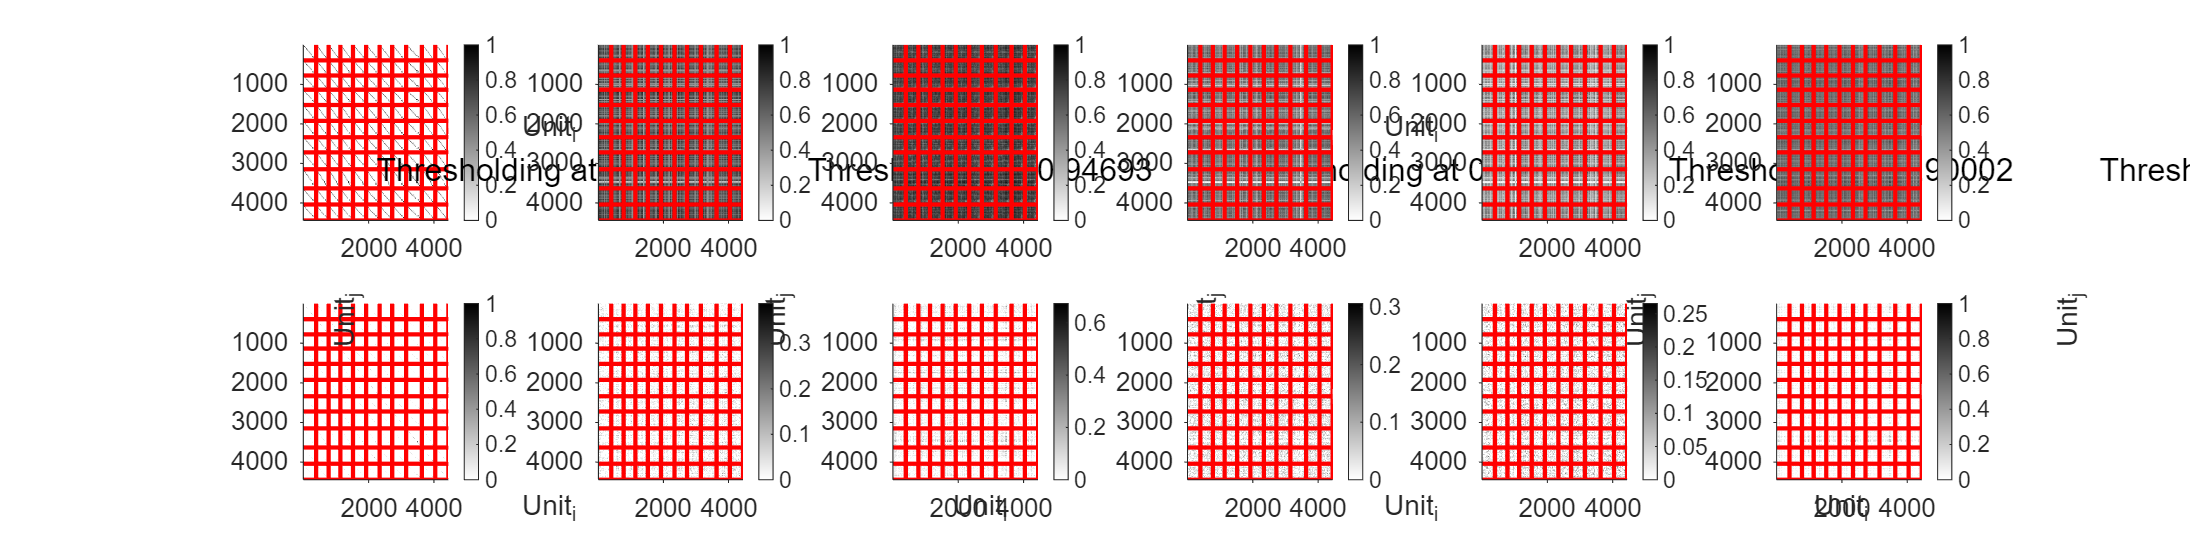

Median drift recording 1 calculated: X=0, Y=-0.037249, Z=-2.4754
Median drift recording 2 calculated: X=0, Y=0, Z=-2.6435
Median drift recording 3 calculated: X=0, Y=0, Z=-1.2185
Median drift recording 4 calculated: X=0, Y=0, Z=-0.61124
Median drift recording 5 calculated: X=0, Y=-0.0029496, Z=-0.30513
Median drift recording 6 calculated: X=0, Y=0.0046901, Z=-0.39846
Median drift recording 7 calculated: X=0, Y=0, Z=-0.1243
Median drift recording 8 calculated: X=0, Y=-0.12433, Z=-2.5188
Median drift recording 9 calculated: X=0, Y=-1.1369e-13, Z=-0.28273
Median drift recording 10 calculated: X=0, Y=-0.052137, Z=-2.7049


priorMatch = 0.9983

Creating the Naive Bayes model...
Average cross-validation match = 0 performance: 100%
Average cross-validation match = 1 performance: 98%
Done in 97s.
Getting the Naive Bayes model took 163.9783 seconds for 4443 units
Extracting final pairs of units...


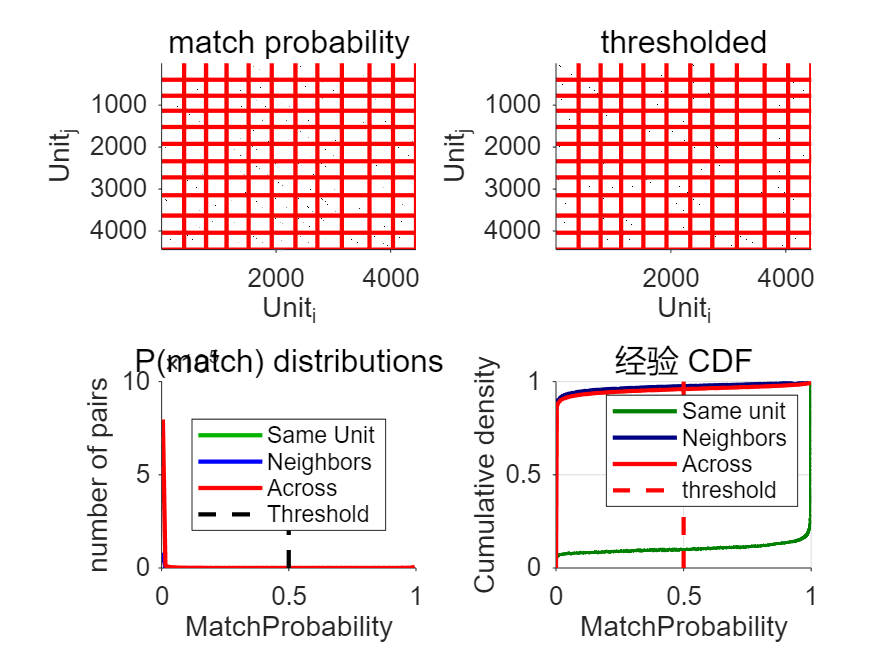

Extracting final pair of units took 64.0636 seconds for 4443 units
Evaluating Naive Bayes...
90% of units were matched with itself
False negative estimate: 9.99%
False positive estimate recording 1: 1.44%
False positive estimate recording 2: 1.51%
False positive estimate recording 3: 1.33%
False positive estimate recording 4: 1.26%
False positive estimate recording 5: 1.35%
False positive estimate recording 6: 1.16%
False positive estimate recording 7: 1.74%
False positive estimate recording 8: 1.71%
False positive estimate recording 9: 1.78%
False positive estimate recording 10: 1.83%
False positive estimate recording 11: 1.3%


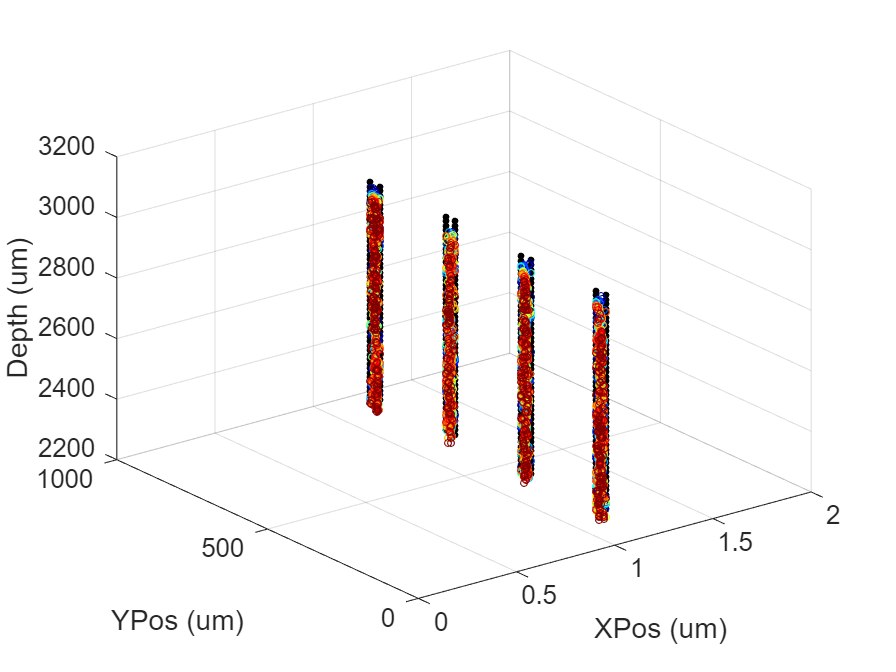

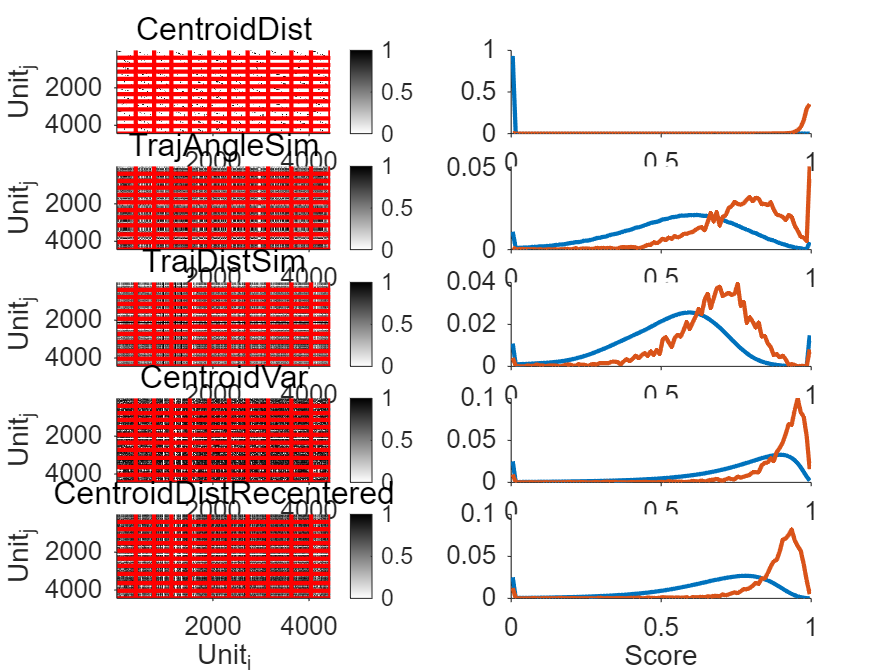

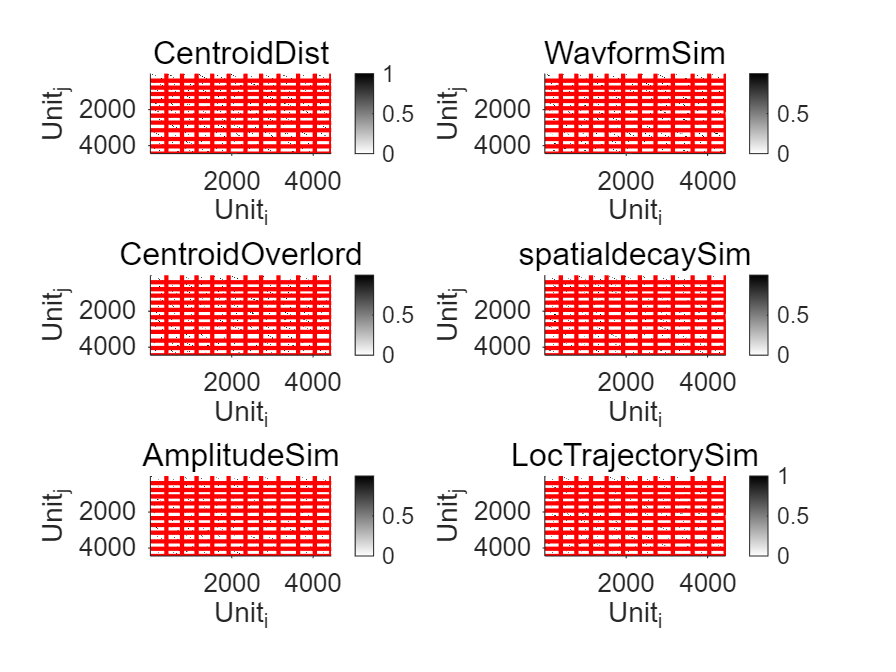

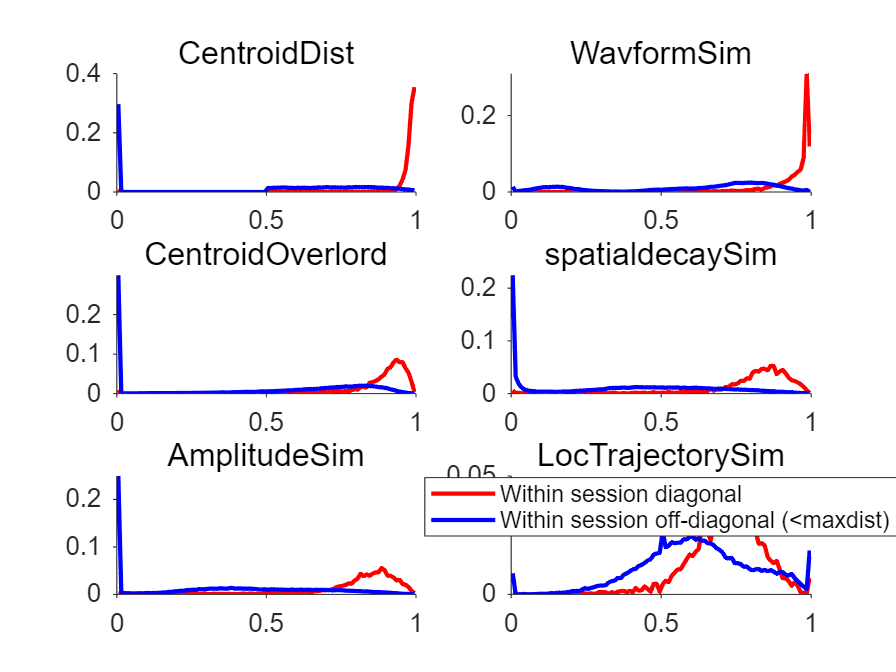

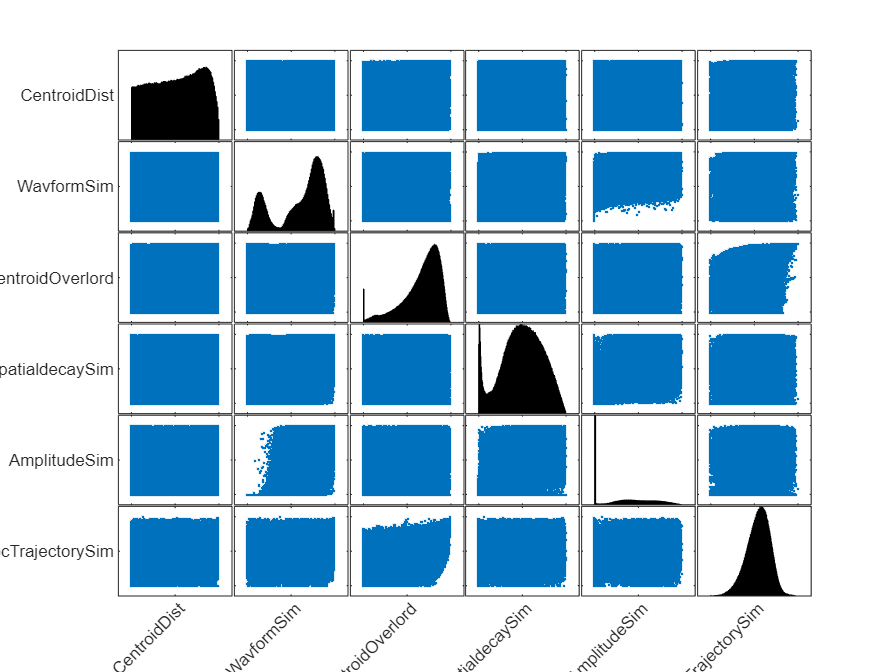

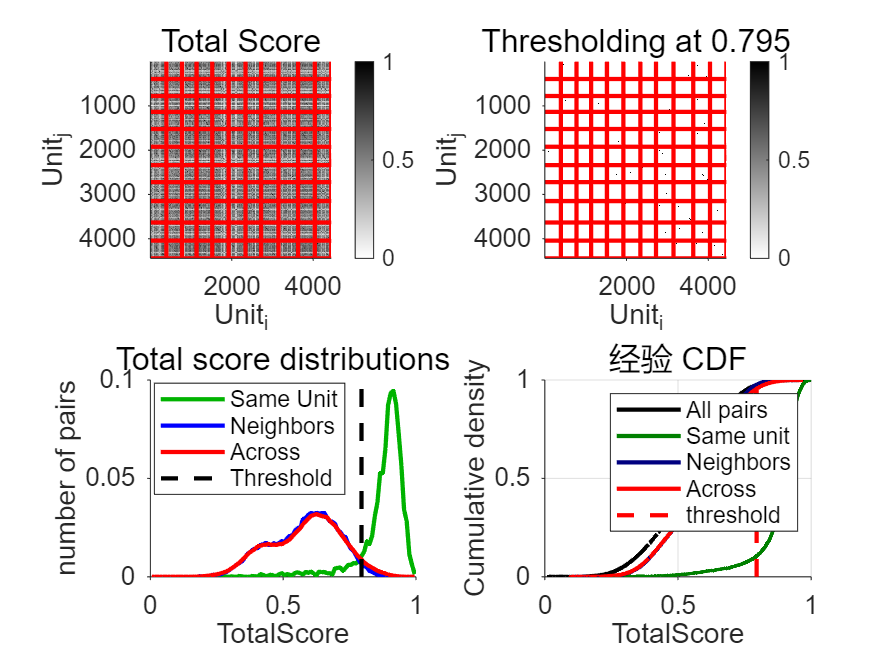

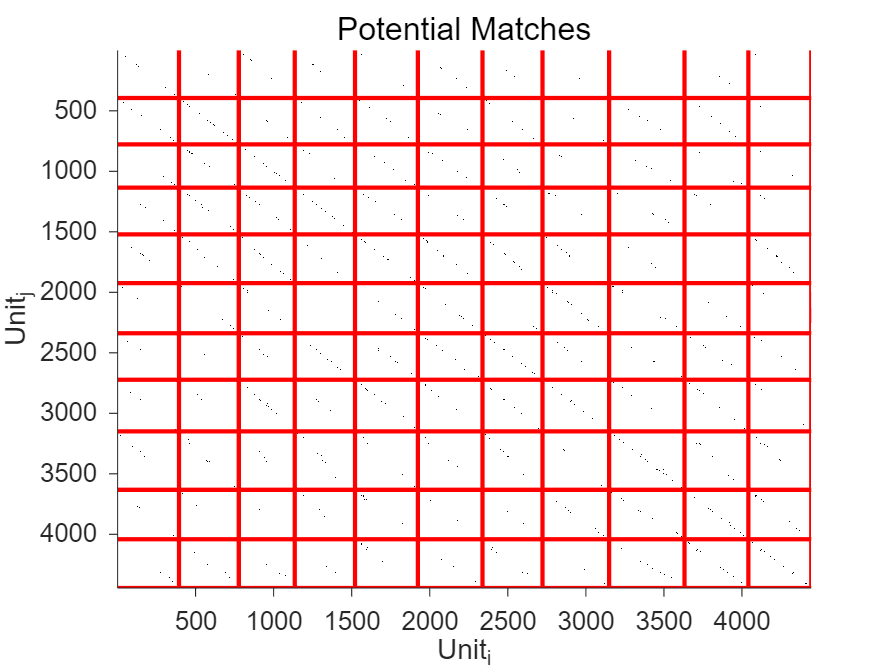

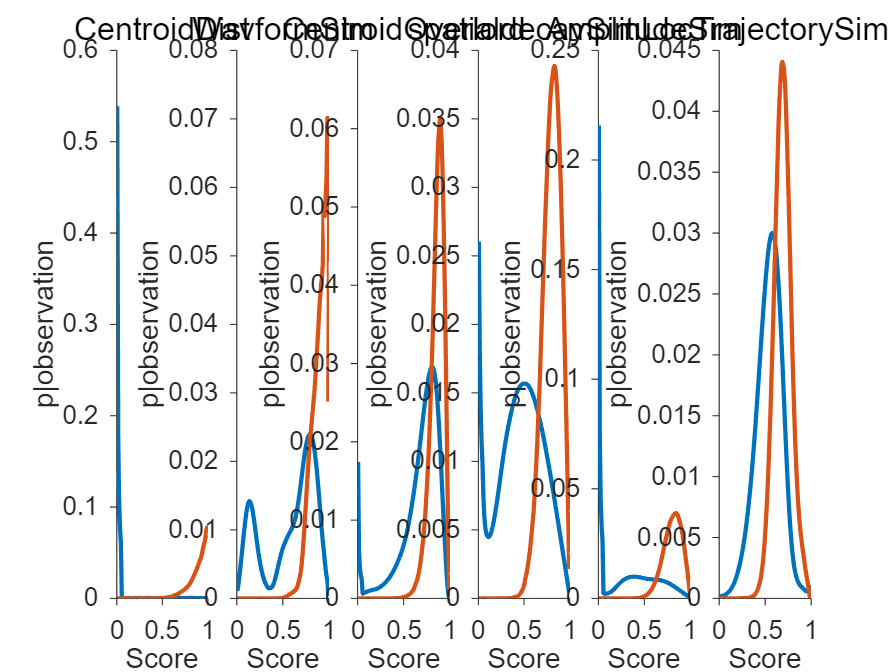

% Obtain the probability for each pair of units of being a "match"
[UniqueIDConversion, MatchTable, WaveformInfo, UMparam] = UnitMatch(clusinfo, UMparam);


% Apply tracking algoritms based on UnitMatch's output probabilities
if UMparam.AssignUniqueID
    [UniqueIDConversion, MatchTable] = AssignUniqueID(UMparam.SaveDir);
end

Loading match table to assign Unique IDs...
Assigning correct Unique ID values now
Used Probability = 0.85
Assigning pairs. Progress: 100%7737 liberal matches/4443
3567 conservative matches/4443
4277 intermediate matches/4443
Saving table


## '-- Evaluating the output -- (optional)

## If you want, you can run additional scripts to evaluate the results:

Evaluating the model as it was ran by user


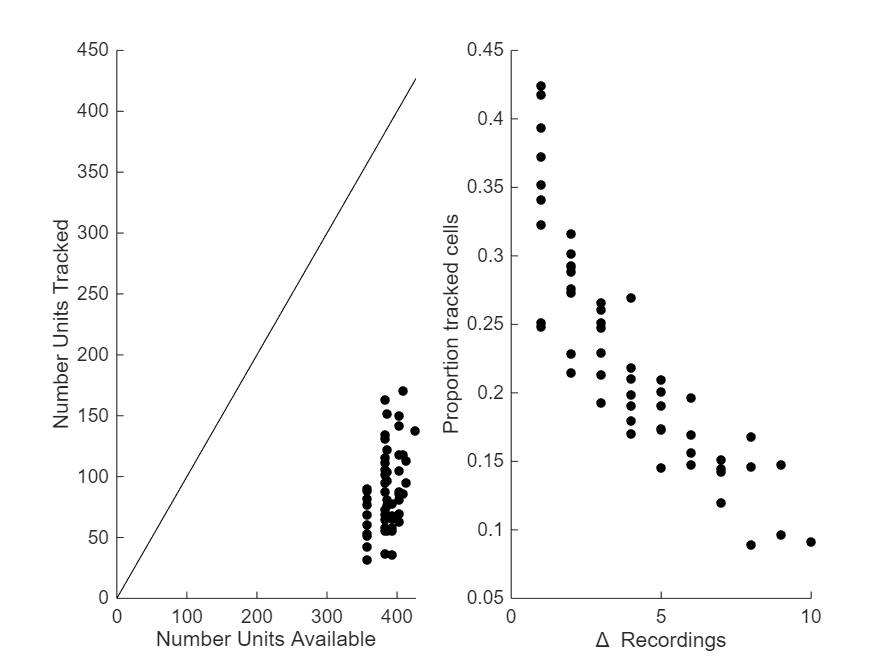

Within recording cross-validation: PyKS was ran on individual sessions


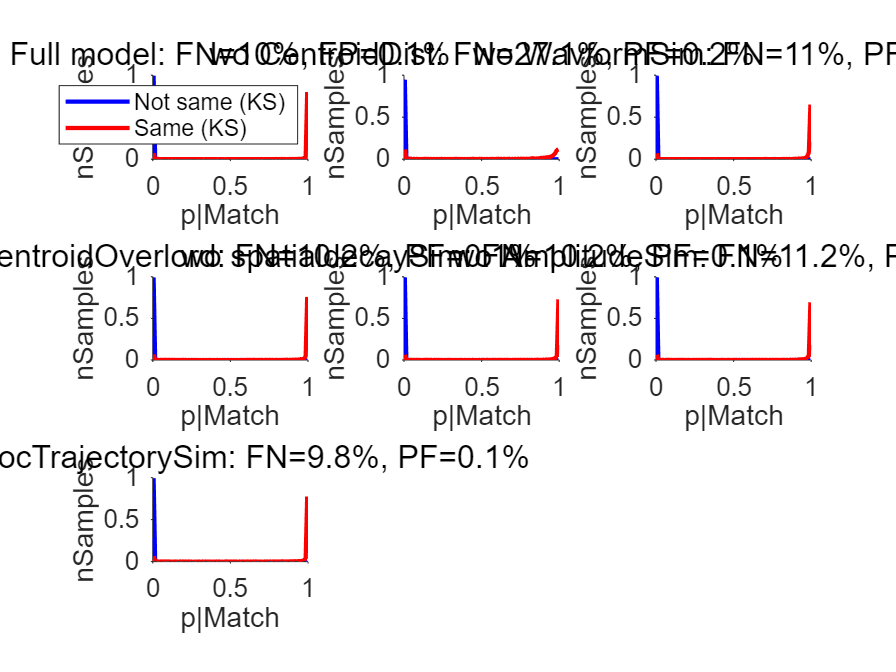

False negative rate: 10%
False positive rate: 0.1%
We advise to use the model you just used on this data:
This parameter set is probably the best


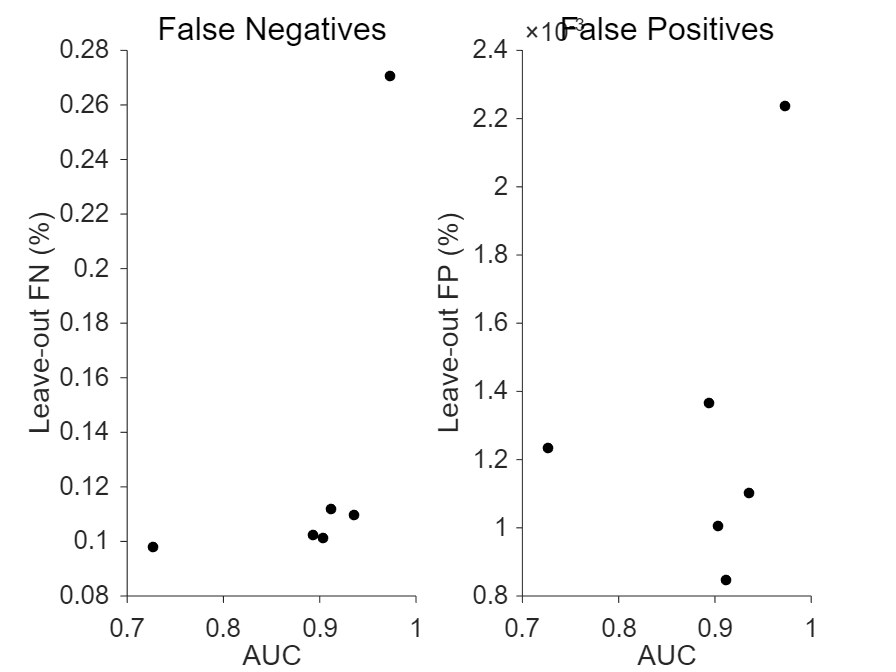

AUC order:


ans = 1×13 cell 数组
    {'CentroidDist'}    {'WavformSim'}    {'WVCorr'}    {'WavformMSE'}    {'AmplitudeSim'}    {'spatialdecaySim'}    {'CentroidOverlord'}    {'CentroidDistRecentered'}    {'CentroidVar'}    {'spatialdecayfitSim'}    {'TrajAngleSim'}    {'LocTrajectorySim'}    {'TrajDistSim'}


ans =     0.9737    0.9356    0.9347    0.9336    0.9117    0.9037    0.8939    0.8936    0.8708    0.8531    0.7718    0.7269    0.6015


% Within session cross-validation
EvaluatingUnitMatch(UMparam.SaveDir);

% Evaluating the matching using functional scores (only works when having access to Kilosort output, e.g. spike times etc. )
ComputeFunctionalScores(UMparam.SaveDir)

Loading spike information...
Computing cross-correlation fingerprint
Computing ISI, this will take some time...


错误使用 histcounts>validateBinNumber (第 420 行)
'NumBins' 必须为有限实数正整数值。

出错 histcounts (第 71 行)
            validateBinNumber(a);

出错 ComputeFunctionalScores (

disp(class(UMparam.SaveDir))
disp(UMparam.SaveDir)
disp(class(['TrackingPerformance ', UMparam.SaveDir]))

## You can also visualize the units on the probe:

PlotUnitsOnProbe(clusinfo,UMparam,UniqueIDConversion,WaveformInfo)

%% Curation:
%
% if UMparam.MakePlotsOfPairs
%     DrawPairsUnitMatch(UMparam.SaveDir);
%     if UMparam.GUI
%         FigureFlick(UMparam.SaveDir)
%         pause
%     end
% end
% %%
% if true
%     DrawPairsUnitMatch(UMparam.SaveDir);
%     if true
%
%         FigureFlick(UMparam.SaveDir)
%         pause
%     end
% end
% %%
% if true
%     FigureFlick(UMparam.SaveDir)
%     pause
% end

## If using bombcell

% Evaluating how much quality metrics predict "matchability" (only works in combination with bombcell)
QualityMetricsROCs(UMparam.SaveDir);

## The following scripts work with several animals and plot summaries of the matching evaluation.

UMFiles = {fullfile(UMparam.SaveDir,'UnitMatch.mat')}; % cell containing a list of all the UnitMatch outputs you want to combine -- let's use one for now.
groupvec = 1; % How do you want to group these outputs? E.g., group all the outputs from the same animal into one

% Plots a summary of the functional metrics results
summaryFunctionalPlots(UMFiles, 'Corr', groupvec);

% Plots a summary of the matching probability
summaryMatchingPlots(UMFiles);